% Locate the TVALID and TLAST control signals of the FFT
fft_out_tvalid = out.TVALID

fft_out_tvalid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tvalid == 1, 1)

ans = 4232

fft_out_tlast = out.TLAST

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


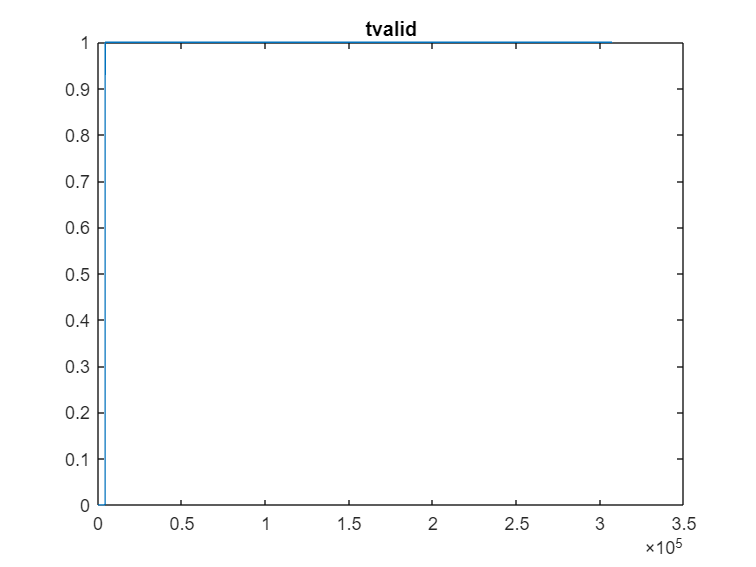

plot(1:length(fft_out_tvalid),fft_out_tvalid)
title('tvalid')

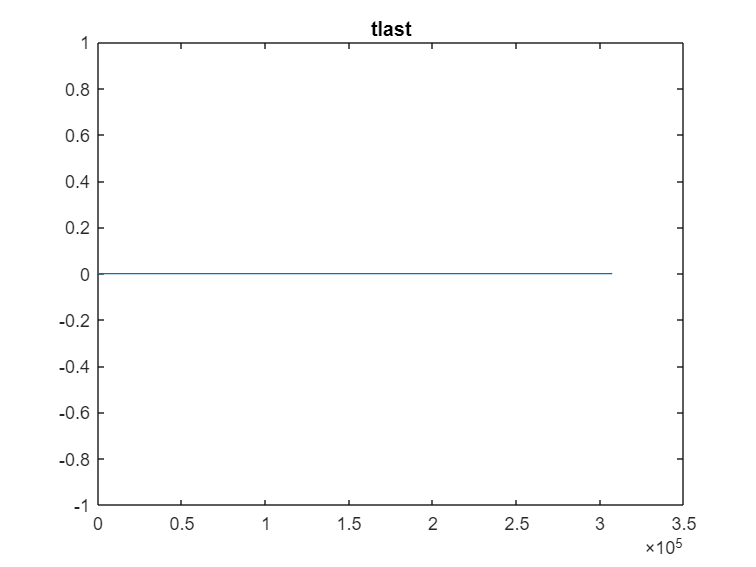

plot(1:length(fft_out_tlast),fft_out_tlast)
title('tlast')


% Locate the FFT data output
fft_out_log_ = out.FFT_out_log

fft_out_log_ =   -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf


% Only keep the valid samples
fft_out_log = fft_out_log_(find(fft_out_tvalid == 1, 1):end)

fft_out_log =  -109.1212
 -108.9858
 -108.8481
 -108.6073
 -108.4710
 -108.4710
 -108.3327
 -107.9648
 -107.7391
 -107.6041


% Zero-pad if neccessary to ensure # samples is an integer multiple of the
% window size (required for easier spectrogram plotting)
fft_length_before_zero_padding = (ceil(length(fft_out_log)/N))

fft_length_before_zero_padding = 148


% Set the zero-padded values to the minimum value of the valid samples
fft_out_log(length(fft_out_log)+1:fft_length_before_zero_padding*N)=min(fft_out_log)

fft_out_log =  -109.1212
 -108.9858
 -108.8481
 -108.6073
 -108.4710
 -108.4710
 -108.3327
 -107.9648
 -107.7391
 -107.6041



% Determine key parameters
Total_Num_Samples = length(fft_out_log)

Total_Num_Samples = 303104

Num_Segments = Total_Num_Samples/N

Num_Segments = 148


% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,Total_Num_Samples/fs,Num_Segments)

t_axis_1N = 1.0e-03 *

         0    0.0067    0.0134    0.0201    0.0268    0.0336    0.0403    0.0470    0.0537    0.0604    0.0671    0.0738    0.0805    0.0873    0.0940    0.1007    0.1074    0.1141    0.1208    0.1275    0.1342    0.1410    0.1477    0.1544    0.1611    0.1678    0.1745    0.1812    0.1879    0.1946    0.2014    0.2081    0.2148    0.2215    0.2282    0.2349    0.2416    0.2483    0.2551    0.2618    0.2685    0.2752    0.2819    0.2886    0.2953    0.3020    0.3088    0.3155    0.3222    0.3289


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.0067    0.0134    0.0201    0.0268    0.0336    0.0403    0.0470    0.0537    0.0604    0.0671    0.0738    0.0805    0.0873    0.0940    0.1007    0.1074    0.1141    0.1208    0.1275    0.1342    0.1410    0.1477    0.1544    0.1611    0.1678    0.1745    0.1812    0.1879    0.1946    0.2014    0.2081    0.2148    0.2215    0.2282    0.2349    0.2416    0.2483    0.2551    0.2618    0.2685    0.2752    0.2819    0.2886    0.2953    0.3020    0.3088    0.3155    0.3222    0.3289


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis =          0    0.1500    0.3000    0.4500    0.6000    0.7500    0.9000    1.0500    1.2000    1.3500    1.5000    1.6500    1.8000    1.9500    2.1000    2.2500    2.4000    2.5500    2.7000    2.8500    3.0000    3.1500    3.3000    3.4500    3.6000    3.7500    3.9000    4.0500    4.2000    4.3500    4.5000    4.6500    4.8000    4.9500    5.1000    5.2500    5.4000    5.5500    5.7000    5.8500    6.0000    6.1500    6.3000    6.4500    6.6000    6.7500    6.9000    7.0500    7.2000    7.3500


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =  -153.6000 -153.4500 -153.3000 -153.1500 -153.0000 -152.8500 -152.7000 -152.5500 -152.4000 -152.2500 -152.1000 -151.9500 -151.8000 -151.6500 -151.5000 -151.3500 -151.2000 -151.0500 -150.9000 -150.7500 -150.6000 -150.4500 -150.3000 -150.1500 -150.0000 -149.8500 -149.7000 -149.5500 -149.4000 -149.2500 -149.1000 -148.9500 -148.8000 -148.6500 -148.5000 -148.3500 -148.2000 -148.0500 -147.9000 -147.7500 -147.6000 -147.4500 -147.3000 -147.1500 -147.0000 -146.8500 -146.7000 -146.5500 -146.4000 -146.2500


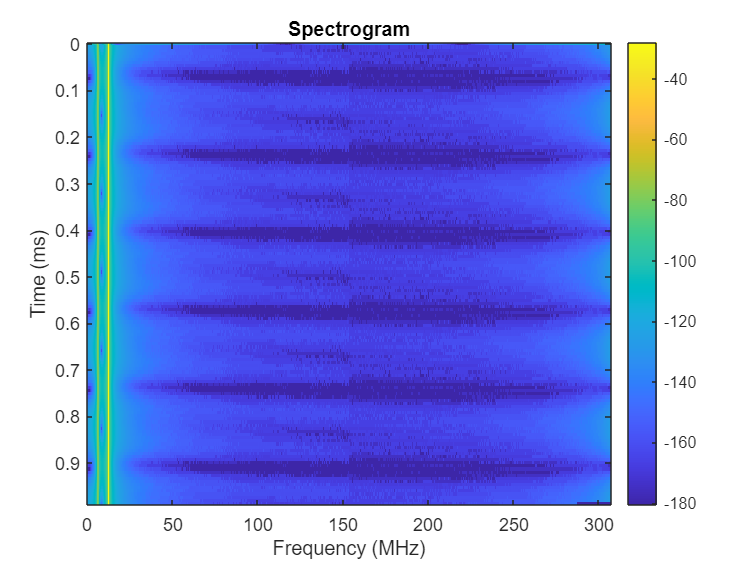


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);
    Data(i,:) = fft_out_log(index);
    Data_(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

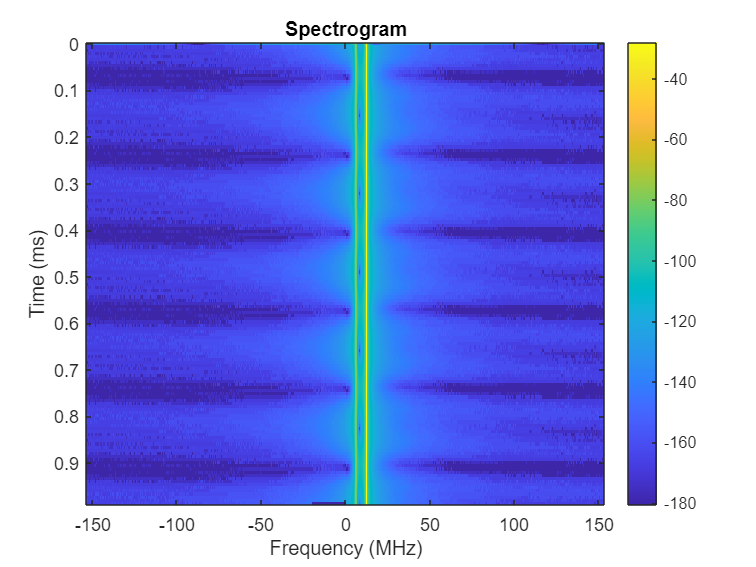

figure;
imagesc(f_axis_,t_axis,Data_)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar